## Hard Decision Decoding Code for large H matrices 

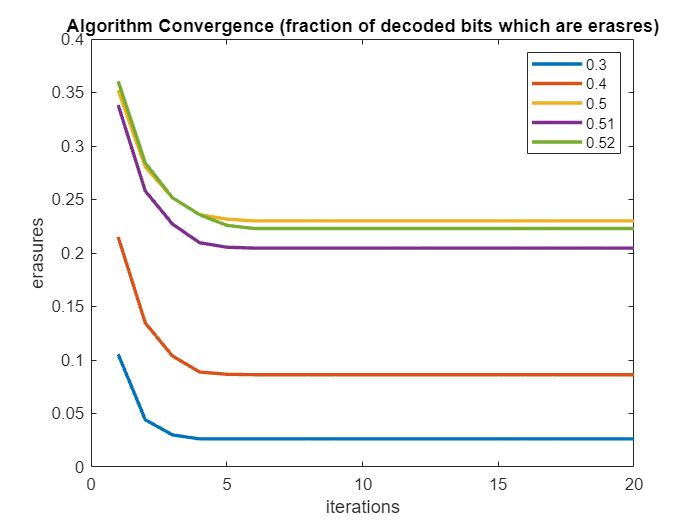

%%Getting information about the preloaded matrix H
%% or enter the H matrix here
H = [1 0 0 0 0 1 0 1 0 1 0 0;
 1 0 0 1 1 0 0 0 0 0 1 0;
 0 1 0 0 1 0 1 0 1 0 0 0;
 0 0 1 0 0 1 0 0 0 0 1 1;
 0 0 1 0 0 0 1 1 0 0 0 1;
 0 1 0 0 1 0 0 0 1 0 1 0;
 1 0 0 1 0 0 1 0 0 1 0 0;
 0 1 0 0 0 1 0 1 0 1 0 0;
 0 0 1 1 0 0 0 0 1 0 0 1];
%columns
col = length(H);
%row
row = height(H);
%degree of checknodes
dc = getdc(H);
%degree of variable nodes 
dv = getdv(H);
%connections of all the CNs
map_of_CN = getCNmap(dc,H);
%connections of all the VNs
map_of_VN = getVNmap(dv,H);
%transmitted message 
transmit_msg = zeros(1,col);

%number of repititions/simulations
Nsim = 200;

%maximum number of iterations 
max_it = 20;
no_of_it = 1:1:max_it;

for p = [0.3, 0.4, 0.5, 0.51, 0.52]
    erasure = zeros(1,max_it);
    error = zeros(1,max_it);
        count = 0;
        count_erasure = 0;
        
        for L = 1:1:Nsim

            received_msg = get_off_bec(transmit_msg,p,col);
            currMsg = received_msg;
            sentfromCN = zeros(size(map_of_CN));
            receivedtoVN = zeros(size(map_of_VN));
            sentfromVN = zeros(size(map_of_VN));
            receivedtoCN = zeros(size(map_of_CN));
            flagy = 0;

            for it = 1:1:max_it

                prevMsg = currMsg;
                if it==1
                    sentfromCN = spc0(received_msg,map_of_CN);
                else
                    sentfromVN =  repititioncode(receivedtoVN, received_msg,map_of_VN);
                    receivedtoCN = CNreceival(sentfromVN,map_of_VN,map_of_CN);
                    sentfromCN = spc(receivedtoCN, map_of_CN);   
                end

                receivedtoVN = VNreceival(sentfromCN,map_of_CN,map_of_VN);
                currMsg = repetitioncode(receivedtoVN,received_msg);              

                erasureno = 0;
                myflag = 0;
                 for i=1:length(currMsg)
                     if currMsg(i) == -1
                         erasureno = erasureno+1;
                         myflag = 1;
                     end
                 end

                error(it) = error(it) + myflag;
 
                erasure(it) = erasure(it)+(erasureno/length(received_msg));
    
                if checkerasure(currMsg) == 0
                    flagy = it;
                    break;
                end
                
            end

        end
        erasure = erasure./Nsim;
        error = error./Nsim;

plot(no_of_it,erasure, LineWidth = 2);
hold on;

end

legend('0.3','0.4','0.5','0.51','0.52');
title('Algorithm Convergence (fraction of decoded bits which are erasres)');
xlabel('iterations');
ylabel('erasures');

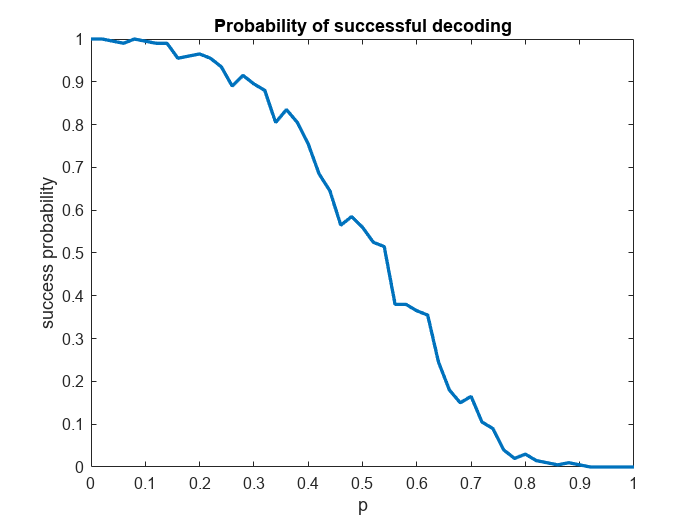


%probability of successful decoding with different p 
pbec = 0:0.02:1;
successProb = zeros(size(pbec));
index=1;
for p = pbec
    count_success = 0;
        for L = 1:1:Nsim
           
            received_msg = get_off_bec(transmit_msg,p,col);
            currMsg = received_msg;
            sentfromCN = zeros(size(map_of_CN));
            receivedtoVN = zeros(size(map_of_VN));
            sentfromVN = zeros(size(map_of_VN));
            receivedtoCN = zeros(size(map_of_CN));
            for it = 1:1:max_it
                prevMsg = currMsg;
    
                if it==1
                    sentfromCN = spc0(received_msg,map_of_CN);
                else
                    sentfromVN =  repititioncode(receivedtoVN, received_msg,map_of_VN);
                    receivedtoCN = CNreceival(sentfromVN,map_of_VN,map_of_CN);
                    sentfromCN = spc(receivedtoCN, map_of_CN);
                end
    
                receivedtoVN = VNreceival(sentfromCN,map_of_CN,map_of_VN);
    
                currMsg = repetitioncode(receivedtoVN,received_msg);

            end
            
            if sum(currMsg) == 0
                count_success = count_success + 1;
            end 
             
        end
        successProb(1,index) = count_success/Nsim;
        index=index+1;
end
figure;
plot(pbec,successProb, LineWidth=2);
ylabel('success probability');
title('Probability of successful decoding');
xlabel('p');

function dc = getdc(H)
    dc = 0;
    row = height(H);
    col = length(H);
    for i = 1:row
        tmp = 0;
        for j = 1:col
            if H(i,j) == 1
                tmp = tmp+1;
            end
        end
        if dc<tmp
            dc = tmp;
        end
    end
end

function dv = getdv(H)
    row = height(H);
    col = length(H);
    dv = 0;
    for i = 1:col
        tmp = 0;
        for j = 1:row
            if H(j,i) == 1
                tmp = tmp+1;
            end
        end
        if dv<tmp
            dv = tmp;
        end
    end
end

%cn1 --> vn1, vn2...      map_of_CN(2,3) = 4 => CN 3 is connected to VN 4
function map_of_CN = getCNmap(dc,H)   
    row = height(H);
    col = length(H);
    map_of_CN = zeros(dc,row);
    for i = 1:row
        new_i = 1;
        for j=1:col
            if H(i,j) == 1
                map_of_CN(new_i,i) = j;
                new_i = new_i + 1;
            end
        end
    end
end

%vn1 --> cn1, cn2, ...   map_of_VN(2,4) = 3 => VN 4 is connected to CN 3
function map_of_VN = getVNmap(dv,H)   
    row = height(H);
    col = length(H);
    map_of_VN = zeros(dv,col);
    for i = 1:col
        new_i = 1;
        for j=1:row
            if H(j,i) == 1
                map_of_VN(new_i,i) = j;
                new_i = new_i + 1;
            end
        end
    end
end


function received_msg = get_off_bec(transmit_msg,p,col)
    received_msg = zeros(1,col);
    becNoise = rand(1,col)<p;
    %making the random message with bec error p
    for i = 1:col
        if becNoise(i) == 1
            received_msg(i) = -1;
        else
            received_msg(i) = transmit_msg(i);
        end
    end
end


function check = checkerasure(msg)
    len = length(msg);
    check = 0;
    for i = 1:len
        if msg(i) == -1
            check = 1;
            break;
        end
    end
end

function ansu = spc0(received_msg,map_of_CN)
      
    ansu = zeros(size(map_of_CN));
    [row, col] = size(map_of_CN);

    for i =1:1:col
        
        for j = 1:1:row
            value = 0;
            for k = 1:1:row
                if k~=j

                    if received_msg(map_of_CN(k,i))==-1
                        value = -1;
                        break;
                    end
                    value = mod(value + received_msg(map_of_CN(k,i)) ,2);


                end

            end
            ansu(j,i) = value;

        end
    end


end

function ansu = VNreceival(sentfromCN,map_of_CN,map_of_VN)

    ansu = size(map_of_VN);
    [row, col] = size(map_of_CN);
    

    iterators = ones(1,length(map_of_VN));
    for i = 1:1:col
        for j = 1:1:row
            
            ansu(iterators(1,map_of_CN(j,i)), map_of_CN(j,i)) = sentfromCN(j,i);
            iterators(1,map_of_CN(j,i)) = iterators(1,map_of_CN(j,i))+1;
            

        end
    end


end

function ansu = repetitioncode(receivedtoVN,received_msg)

    ansu = zeros(1,length(received_msg));
    
    [row, col] = size(receivedtoVN);

    for i = 1:1:col

        value = -1;
        if received_msg(1,i)~=-1
                ansu(1,i) = received_msg(1,i);
                
        else
            for j = 1:1:row
                
                    
                if receivedtoVN(j,i)~=-1
                    value = receivedtoVN(j,i);
                    break;
                end
    
    
            end

           ansu(1,i) = value;

        end

    end

end


%sent from VN 

function ansu = repititioncode(receivedtoVN, received_msg,map_of_VN)

    ansu = zeros(size(map_of_VN));
    [row, col] = size(ansu);
    
    for i = 1:col
        for j = 1:row
            ansu(j,i) = -1;
            if received_msg(1,i) ~= -1
                ansu(j,i) = received_msg(1,i);
            else
                for k = 1:row
                    if k ~= j 
                    
                        if receivedtoVN(k,i) ~= -1
                            ansu(j,i) = receivedtoVN(k,i);
                            break;
                        end

                    end
                end
            end
        
        end
    end

end


%received to CN calculations 
function ansu = CNreceival(sentfromVN,map_of_VN,map_of_CN)
    
    ansu = zeros(size(map_of_CN));

    iterators = ones(1,length(map_of_CN));

    [row,col] = size(sentfromVN);

    for i=1:col
        for j = 1:row
            ansu(iterators(1,map_of_VN(j,i)),map_of_VN(j,i)) = sentfromVN(j,i);
            iterators(1,map_of_VN(j,i)) = iterators(1,map_of_VN(j,i)) + 1;
        end
    end

end


%spc1 

function ansu = spc(receivedtoCN, map_of_CN)
    
    ansu = zeros(size(map_of_CN));
    
    [row,col] = size(receivedtoCN);

    for i = 1:col
        for j = 1:row
            value = 0;
            for k = 1:row 
                if k ~= j 
                    if receivedtoCN(k,i) == -1
                        value = -1;
                        break;
                    end
                    value = mod(value+receivedtoCN(k,i),2);
                end
            
            end
            ansu(j,i) = value;
        
        end
    end

end